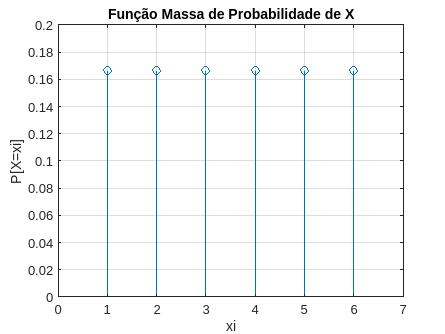

Sx = 1:6;  % espaço de amostragem

probs = ones(1,6)/6; 

stem(Sx, probs)

title('Função Massa de Probabilidade de X')
xlabel('xi')
ylabel('P[X=xi]')
axis([0 7 0 1/5])
grid on

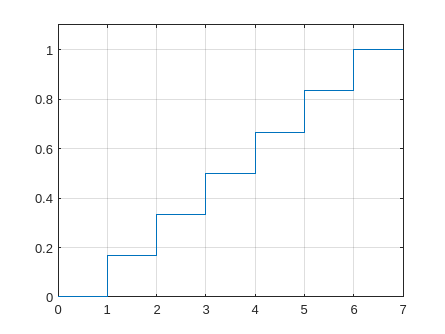

x=1:6;
probs = ones(1,6)/6; 

px = cumsum(probs);
stairs([0 x 7], [0 px 1])
axis([0 7 0 1.1])
grid on

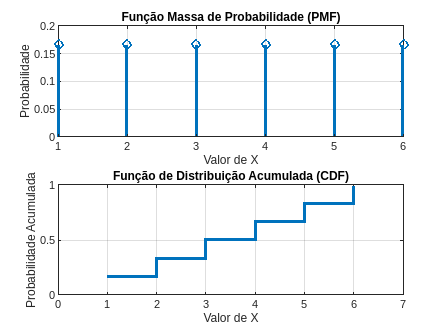

% Definir os valores possíveis da variável aleatória X (as faces do dado)
X = [1, 2, 3, 4, 5, 6];

% Calcular a PMF (probabilidade de cada valor)
PMF = ones(size(X)) / 6;

% Calcular a CDF (soma acumulada da PMF)
CDF = cumsum(PMF);

% Gráfico da PMF
subplot(2, 1, 1);
stem(X, PMF, 'Marker', 'o', 'LineWidth', 2);
title('Função Massa de Probabilidade (PMF)');
xlabel('Valor de X');
ylabel('Probabilidade');
grid on;

% Gráfico da CDF
subplot(2, 1, 2);
stairs(X, CDF, 'LineWidth', 2);
title('Função de Distribuição Acumulada (CDF)');
xlabel('Valor de X');
ylabel('Probabilidade Acumulada');
grid on;

% Ajustar eixos para melhor visualização
axis([0 7 0 1]);